% Importer data
teraterm = importdata("teraterm_log_1")

teraterm = struct with fields:
          data: [11×6 double]
      textdata: {4×6 cell}
    colheaders: {'setpoint'  ' temperatur'  ' fejl'  ' controlsignal'  ' V_sense'  ' V_PT1000'}


temp_ext = importdata("Mappe1.xlsx")'

temp_ext =      8    18    14    26    22    35    44    49    55    56    60


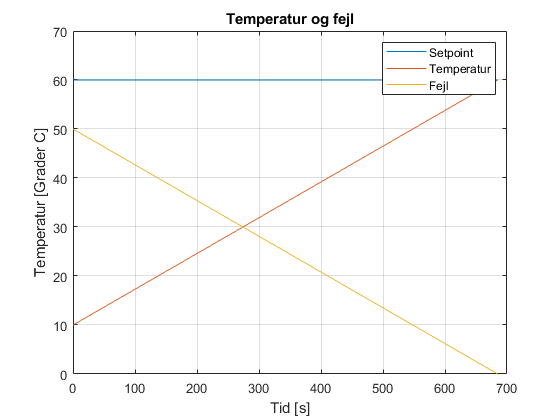


setpoint = teraterm.data(1:end,1)';
temp = teraterm.data(1:end,2)';
error = teraterm.data(1:end,3)';
control_sig = teraterm.data(1:end,4)';
V_sense = teraterm.data(1:end,5)';
V_PT1000 = teraterm.data(1:end,6)';

% Generér tidsakse
Ts = 68.5;
t_akse = (0:Ts:length(temp)*Ts - Ts);

% Plot temperatur og fejl
plot(t_akse, setpoint)
hold on
grid on
title("Temperatur og fejl")
xlabel("Tid [s]")
ylabel("Temperatur [Grader C]")
plot(t_akse, temp)
plot(t_akse, error)
ylim([0 70])
hold off
legend("Setpoint", "Temperatur", "Fejl")

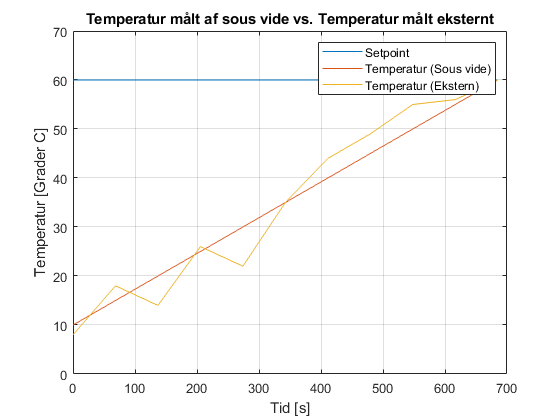


% Plot begge temperaturmålinger
plot(t_akse, setpoint)
hold on
grid on
title("Temperatur målt af sous vide vs. Temperatur målt eksternt")
xlabel("Tid [s]")
ylabel("Temperatur [Grader C]")
plot(t_akse, temp)
plot(t_akse, temp_ext)
ylim([0 70])
hold off
legend("Setpoint", "Temperatur (Sous vide)", "Temperatur (Ekstern)")